# (3). Error correction in NMR

Radiofrequency hardware used to record NMR spectra is not perfect; its principal non-ideality is finite response time: resonant circuits operating at NMR frequencies (hundreds of MHz) take a few microseconds to switch between transmit and receive modes. This introduces three types of distortions:

- **Baseline error**. The first few points of a free induction decay may be distorted. In the frequency domain, the first point of the FID corresponds to uniform vertical shift, and the next few points to  rolling baseline distortions that we will see below.

- **Frequency-independent phase error**. An instrument operating at NMR frequencies cannot keep track of the overall phase of the processing magnetization. A common situation is therefore that the FID is a phase multiplier $e^{\textrm{ia}}$ away from the correctly sampled FID. This does not influence the absolute value but creates unsightly intensity variations in the real and the imaginary part of the NMR spectrum.

- **Frequency-dependent phase error**. After the excitation pulse is finished, the detection does not start immediately - it needs to wait for the electromagnetic ringing to fade in the probe circuit. This means that the time origin of the FID is shifted. By the modulation theorem for the Fourier transform, this corresponds to a frequency-dependent phase error of the form $e^{\textrm{ib}\omega }$ in the NMR spectrum.

In this example, we will learn how to correct all three types of distortions. The molecule we are dealing with here is ethyl crotonate, a plasticiser for acrylic resins; we will be looking at its proton NMR spectrum. Data kindly provided by Prof. Ilya Kuprov, University of Southampton.

### 3.1 Experimental data import

Our dataset has already been exported by the NMR instrument into a [.mat file](https://www.mathworks.com/help/matlab/ref/matlab.io.matfile.html) that may be loaded and plotted directly:

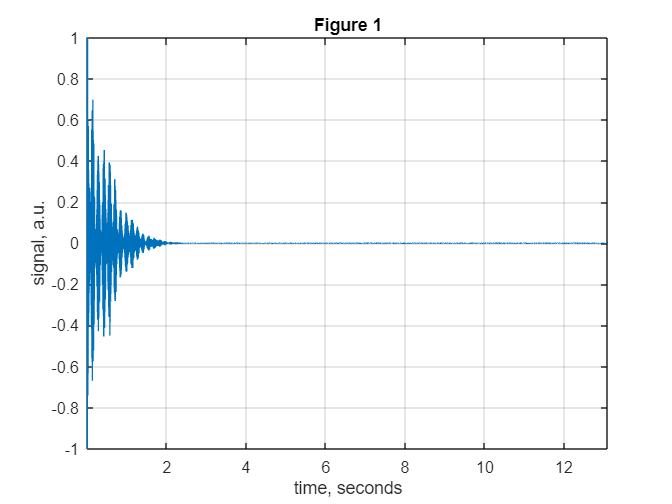

load('ethyl_crotonate.mat','time_axis','ppm_axis','fid');

plot(time_axis,real(fid)); xlim tight; ylim([-1 1]); grid;
xlabel('time, seconds'); ylabel('signal, a.u.'); title('Figure 1');

### **3.2 Phase and baseline inspection**

Note that the time domain signal in Figure 1 is already quite good - it does not require apodisation, DC offset correction, or zerofilling. However, its Fourier transform does show significant phase and background problems:

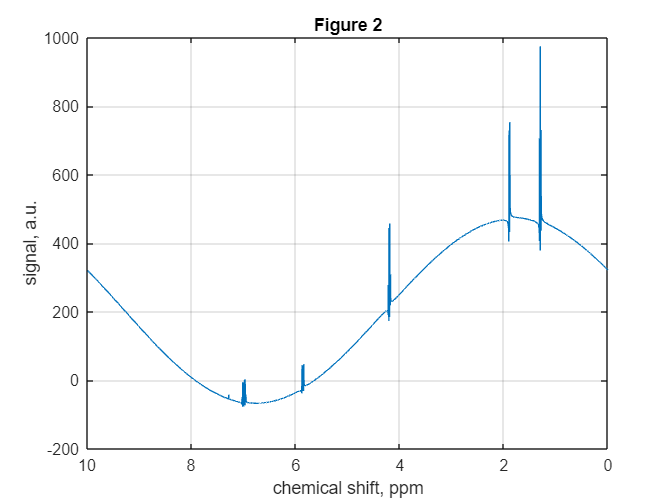

spectrum=fftshift(fft((fid))); 

plot(ppm_axis,real(spectrum)); ylabel('signal, a.u.');
set(gca,'XDir','reverse'); title('Figure 2'); grid;
xlabel('chemical shift, ppm'); 

Here we have plotted the spectrum according to a historical NMR convention - with the chemical shift axis pointing backwards. Our first problem now is the phase: none of the signals in Figure 2 should have any intensity below the baseline.

### **3.3 Phase correction**

From the above, we do know that the phase multiplier has the form $e^{\textrm{ia}+\textrm{ib}\omega }$. We can apply it directly and adjust the coefficients until the spectrum looks like it should:

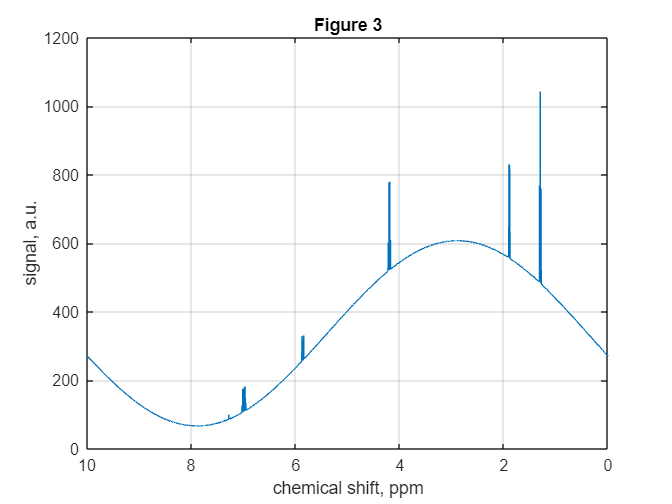

a=0.6974; b=0; omega=linspace(-1,1,numel(spectrum))';
spectrum=real(spectrum.*exp(1i*a+1i*b*omega));

plot(ppm_axis,spectrum); set(gca,'XDir','reverse');
title('Figure 3'); grid; xlabel('chemical shift, ppm'); 
ylabel('signal, a.u.');

The frequency-dependent phase correction term appears to be negligible in this case. The phase is now fixed, but we still have the baseline problem.

### **3.4 Baseline Correction**

The simplest way to remove the baseline distortion is to fit the signal-free parts with a polynomial and subtract the polynomial out. We can visually identify signal-free areas of the spectrum and create a logical array of the same size as the axis tick array that contains *true* when there are no signals:

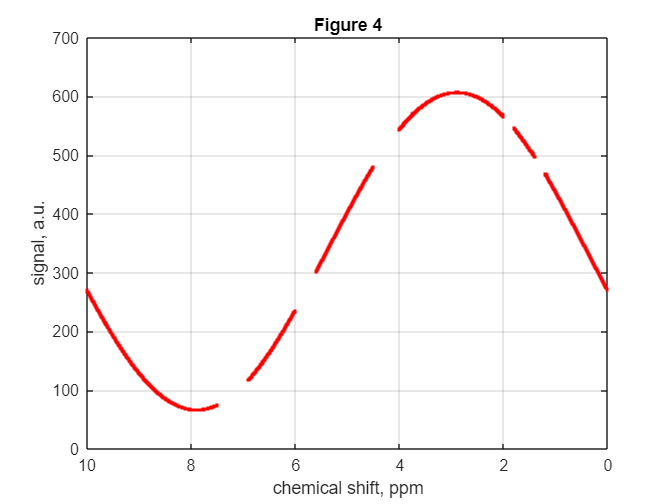

signal_free=(ppm_axis>7.5)&(ppm_axis<10.0)|...
            (ppm_axis>6.0)&(ppm_axis<6.9)|...
            (ppm_axis>4.5)&(ppm_axis<5.6)|...
            (ppm_axis>2.0)&(ppm_axis<4.0)|...
            (ppm_axis>1.4)&(ppm_axis<1.8)|...
            (ppm_axis>0.0)&(ppm_axis<1.2);
plot(ppm_axis(signal_free),spectrum(signal_free),'r.');
set(gca,'XDir','reverse'); title('Figure 4'); grid;
xlabel('chemical shift, ppm'); ylabel('signal, a.u.');

We now fit a seventh-order polynomial to this function:

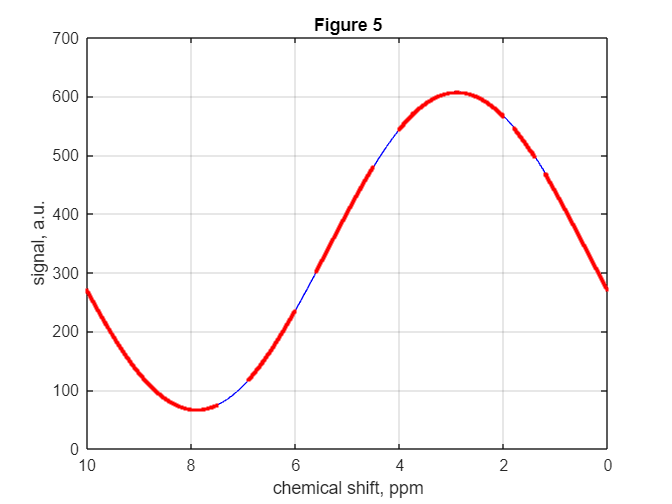

coeffs=polyfit(ppm_axis(signal_free),spectrum(signal_free),7);
baseline=polyval(coeffs,ppm_axis); 

figure(); hold on; plot(ppm_axis,baseline,'b-');
plot(ppm_axis(signal_free),spectrum(signal_free),'r.');
set(gca,'XDir','reverse'); ylabel('signal, a.u.');
title('Figure 5'); grid; box on; hold off;
xlabel('chemical shift, ppm');  

Finally, we can subtract the baseline and obtain our final NMR spectrum:

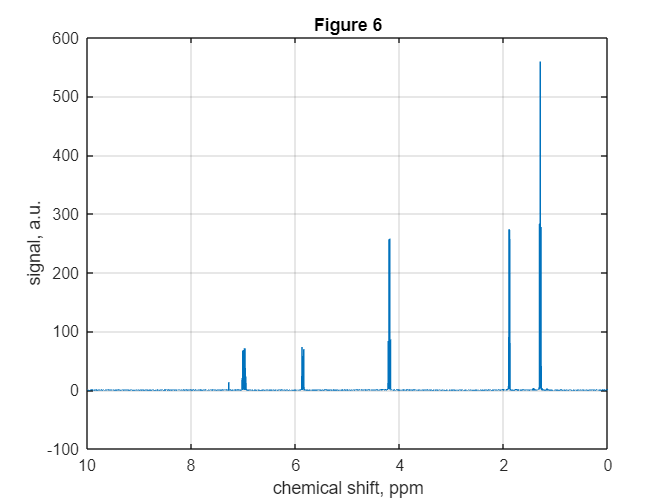

spectrum=spectrum-baseline;

plot(ppm_axis,spectrum); set(gca,'XDir','reverse');
title('Figure 6'); grid; box on; ylabel('signal, a.u.');
xlabel('chemical shift, ppm'); 